clearvars; close all; clc;

# Livescript to test the simulation class

2024-03-21, JVsound

% Create a simulation object:
sim1        = acoustics.simulation;

% Assign a frequency vector:
sim1.f      = logspace(1,3,1e2);

% Add a closed box with a certain volume:
sim1.encl   = enclosure.closedbox(100e-3);

% Extract the acoustic impedance of the closedbox:
zarear      = sim1.encl.zarear;

Plot acoustic impedance of closed box:

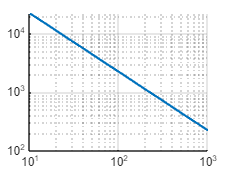

fig1        = figure;
ax1         = axes(fig1); hold on; grid on;
ax1.XScale  = "log";
ax1.YScale  = "log";

plot(ax1,sim1.f,abs(zarear),LineWidth=1.5);